After the inference is performed for the community case, (which can be done by the script files), we perfrom various validation tests. Some of them are shown in this example notebook. All codes are avaible as scripts or tools.

Firstly we show tests for convergence:

load('./../figures/chain_combined.mat');

grand_mean = (mean_chain_1 + mean_chain_2 )/2;

%chain_1 and chain_2 are the chains.

B = N/(M-1) * ((mean_chain_1 - grand_mean).^2 + (mean_chain_2 - grand_mean).^2) ;

v_1 = (std(chain_1)).^2 ;
v_2 = (std(chain_2)).^2 ;

W = (1/M) * (v_1 + v_2) ;



R =  ( (N-1)/N * W + (B/N) ) ./W;
R(24) = [];

Now the Gelman Rubin test plots:

%% plot bars


figure(1)
subplot(2,1,1)
b = bar(R,'FaceColor','flat');

for i = 1:5
b.CData(i,:) = [211,23,24]./255;
end

for i = 6:14
b.CData(i,:) = [15,104,82]./255;
end

for i = 15:23
b.CData(i,:) = [211,119,46]./255;
end

for i=24:32
b.CData(i,:) = [62,137,168]./255;
end



b.CData(33,:) = [217,76,33]./255;
set(gca,'XTickLabel','');
hold on;
line([0.2, 35.8], [1.1, 1.1], 'Color', [0.1,0.1,0.1],'LineStyle','--',LineWidth=2);
set(gca,'FontSize',20);
xlim([0 35])
ylabel('R_{GR}')
ylim([0 1.2])
yticks([0 0.5 1 1.1]);

Now the geweke test bars

store = chainstats(chain_1);

MCMC statistics, nsimu = 10000

      mean         std      MC_err         tau      geweke
----------------------------------------------------------
  0.098496    0.017004   0.0015792      106.24     0.93956
  0.086781    0.022143   0.0023597      104.96     0.94899
  0.018441     0.01343   0.0014589      117.86     0.90139
   0.33332    0.017818   0.0025657      457.59     0.95099
    0.4875     0.02225    0.002355      117.59     0.99648
    285.41    0.027412   0.0036058      292.19     0.99995
    316.03    0.051235   0.0067916      211.32     0.99991
    426.23     0.03248   0.0038391      195.29     0.99994
    261.38    0.025038   0.0031335      218.59     0.99994
    86.125    0.033966   0.0034678       138.3     0.99981
     172.4    0.021483   0.0030284      348.54     0.99996
    395.47    0.027687   0.0034785      211.17     0.99996
     143.5    0.032051   0.0039558      176.96           1
    14.326    0.035882   0.0043197      160.67     0.99955
   -7.5826    0.028902  

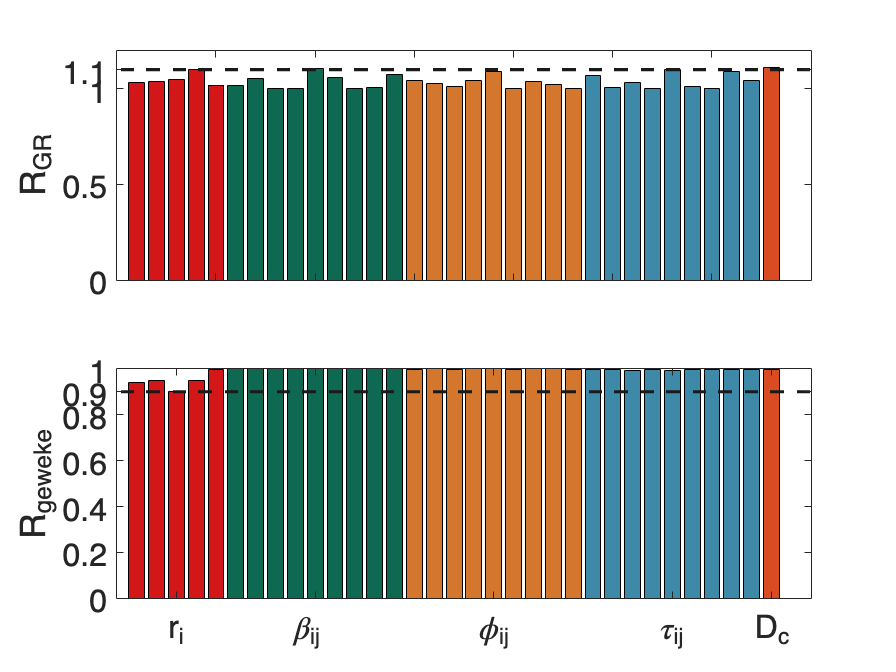

R_geweke = store(:,5);
R_geweke(24) = [];

subplot(2,1,2)
b = bar(R_geweke,'FaceColor','flat');

for i = 1:5
b.CData(i,:) = [211,23,24]./255;
end

for i = 6:14
b.CData(i,:) = [15,104,82]./255;
end

for i = 15:23
b.CData(i,:) = [211,119,46]./255;
end

for i=24:32
b.CData(i,:) = [62,137,168]./255;
end



b.CData(33,:) = [217,76,33]./255;
set(gca,'XTickLabel','');
hold on;
line([0.2, 38], [0.9, 0.9],'Color', [0.1,0.1,0.1],'LineStyle','--',LineWidth=2  );
set(gca,'FontSize',20);
xlim([0 35])
ylabel('R_{geweke}')
yticks([0 0.2 0.4 0.6 0.8 0.9 1]);


set(gca, 'XTick', [3 10 19 28 33]);
set(gca, 'XTickLabel', {'r_i' '\beta_{ij} ' '\phi_{ij}' '\tau_{ij}' 'D_c'});

Now showing the traceplots for all the parameters inferred from the SEIVD model

Firstly for burst sizes

addpath('./figures/')

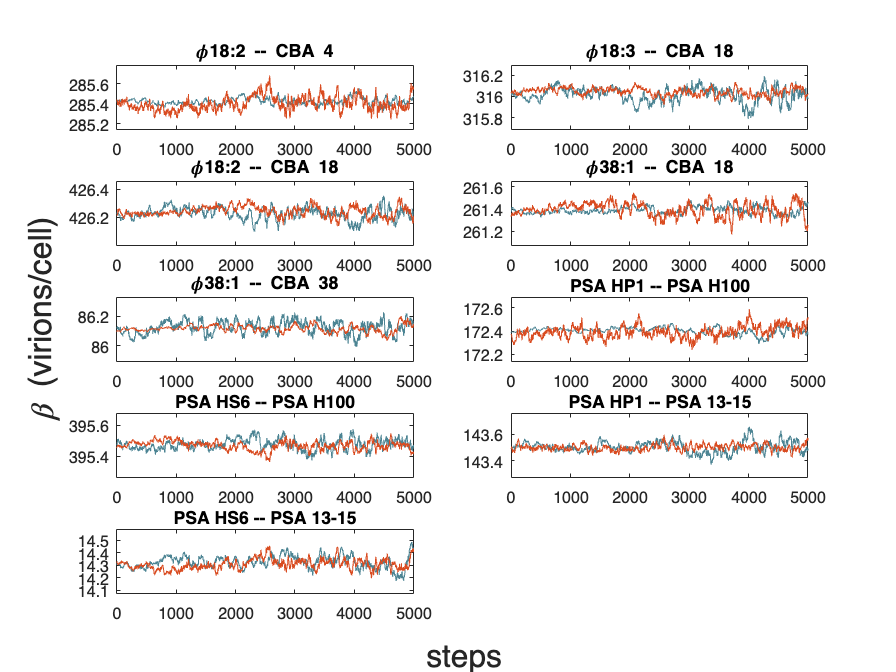

fig1 = figure;

transient_id = 5000;
 

color1 = [76,132,147]./255;
color2 = [217,76,33]./255;

for i = 1:9

subplot(5,2,i)
plot(chain_1(transient_id:end,5+i),'Color',color1 );
xlim([0 5000])
hold on;

end


for i = 1:9

subplot(5,2,i)
plot(chain_2(transient_id:end,5+i),'Color',color2);
ylim([  min(min(chain_1(transient_id:end,5+i)),min(chain_2(transient_id:end,5+i)))-0.1,  max(max(chain_1(transient_id:end,5+i)),max(chain_2(transient_id:end,5+i)))+0.1 ]);
xlim([0 5000])
make_title(i);

end

han=axes(fig1,'visible','off'); 
%han.Title.Visible='on';
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,'\beta (virions/cell)');
xlabel(han,'steps');
%title(han,'yourTitle');
set(gca,'FontSize',18)

For host growth rates

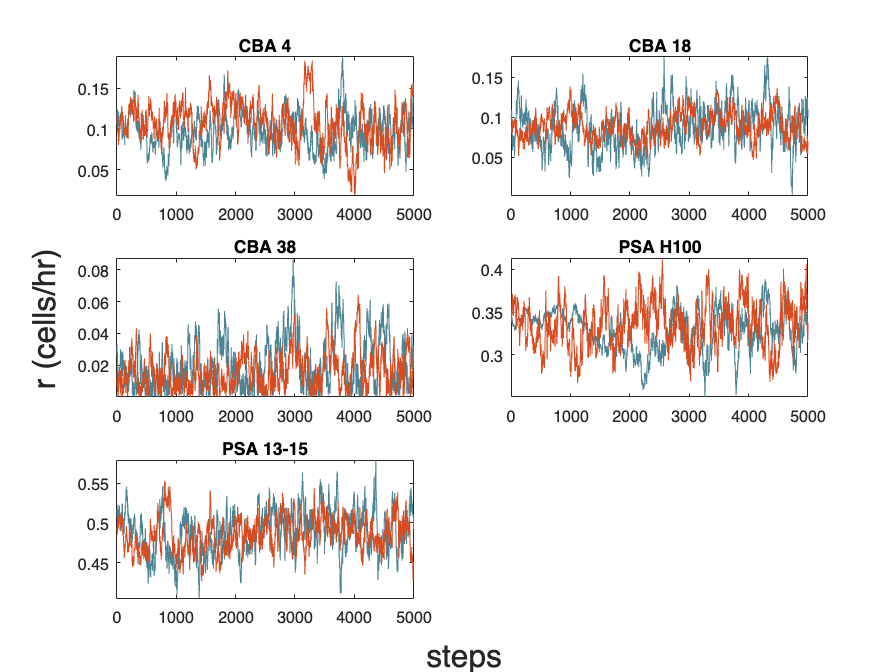

fig2 = figure;

 
for i = 1:5

subplot(3,2,i)
plot(chain_1(transient_id:end,i), 'Color',color1 );
xlim([0 5000])
hold on;

end


for i = 1:5

subplot(3,2,i)
plot(chain_2(transient_id:end,i),'Color',color2);
ylim([  min(min(chain_1(transient_id:end,i)),min(chain_2(transient_id:end,i))),  max(max(chain_1(transient_id:end,i)),max(chain_2(transient_id:end,i))) ]);
xlim([0 5000])
make_title_host(i);

end

han=axes(fig2,'visible','off'); 
%han.Title.Visible='on';
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,'r (cells/hr)');
xlabel(han,'steps');
%title(han,'yourTitle');
set(gca,'FontSize',18)

For viral adsoprtion rates

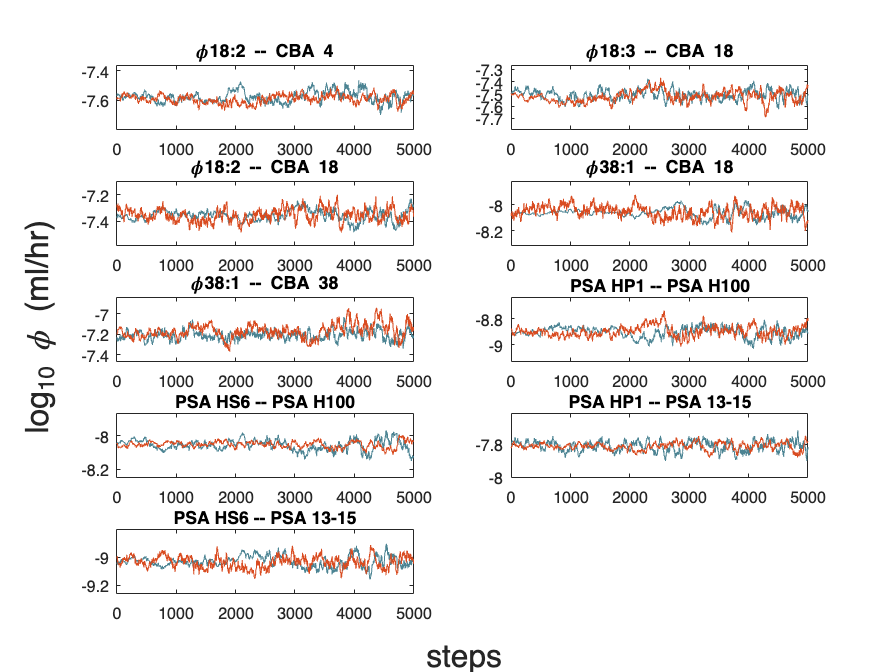

fig3 = figure;


for i = 1:9
subplot(5,2,i)
plot(chain_1(transient_id:end,14+i), 'Color',color1 );
xlim([0 5000])
hold on;
end



for i = 1:9
subplot(5,2,i)
plot(chain_2(transient_id:end,14+i),'Color',color2);
ylim([  min(min(chain_1(transient_id:end,14+i)),min(chain_2(transient_id:end,14+i)))-0.1,  max(max(chain_1(transient_id:end,14+i)),max(chain_2(transient_id:end,14+i)))+0.1 ]);
xlim([0 5000])
make_title(i);
end

han=axes(fig3,'visible','off'); 
%han.Title.Visible='on';
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,'log_{10} \phi (ml/hr) ');
xlabel(han,'steps');
%title(han,'yourTitle');
set(gca,'FontSize',18)

For viral latent periods

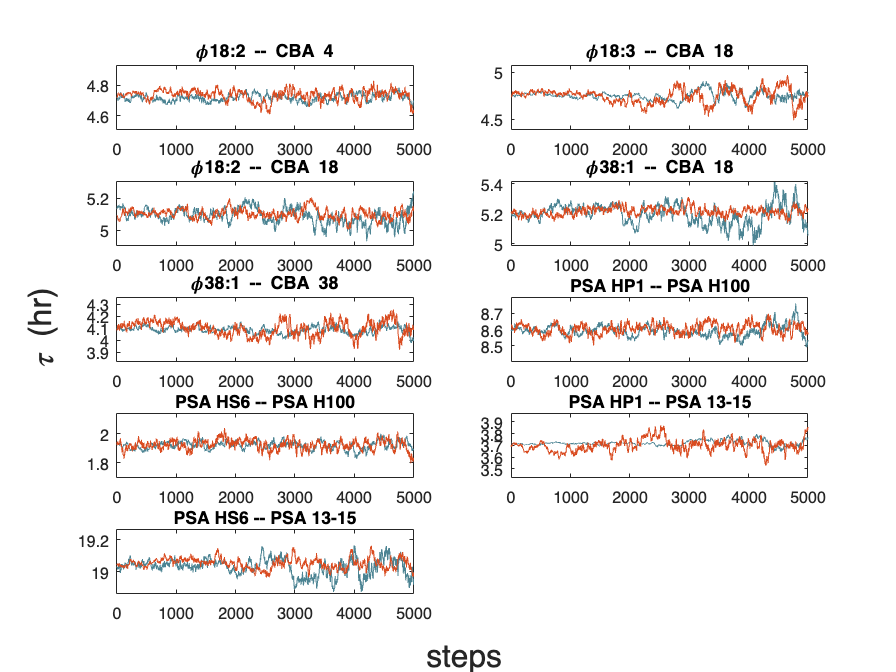

fig4 = figure;

for i = 1:9

subplot(5,2,i)
plot(chain_1(transient_id:end,24+i),'Color',color1);
xlim([0 5000])
hold on;

end



for i = 1:9

subplot(5,2,i)
plot(chain_2(transient_id:end,24+i),'Color',color2);
ylim([  min(min(chain_1(transient_id:end,24+i)),min(chain_2(transient_id:end,24+i)) -0.1) ,  max(max(chain_1(transient_id:end,24+i)),max(chain_2(transient_id:end,24+i)) +0.1)]);

xlim([0 5000])
make_title(i);
end


han=axes(fig4,'visible','off'); 
%han.Title.Visible='on';
han.XLabel.Visible='on';
han.YLabel.Visible='on';
ylabel(han,'\tau (hr) ');
xlabel(han,'steps');
%title(han,'yourTitle');
set(gca,'FontSize',18)